# Tipos de ventana

### Ventana Cuadrada Original

En esta seccion creamos una venta primero creamos zeros y luego ponemos unos en un rango 

close all;
Tobs = 200

Tobs = 200

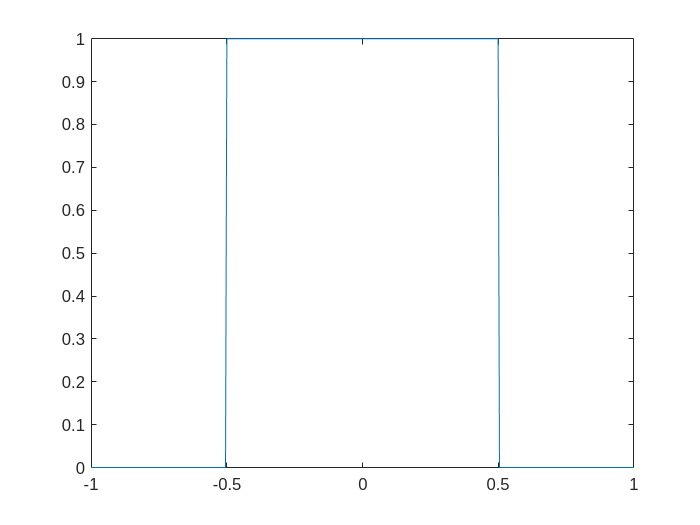

frec=-1:1/Tobs:1;
lenf=length(frec);
x=zeros(1,lenf);
x(101:301)=1;
t_square = real(ftot(x));
plot(frec,x);

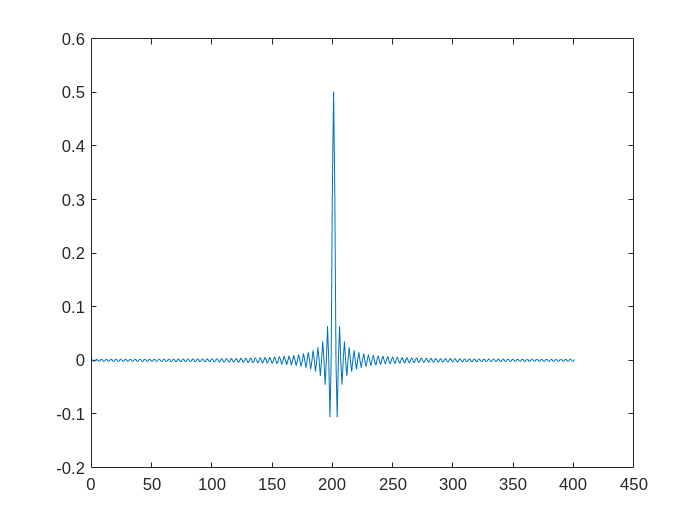

plot(t_square);

### Ventana Uniforme

Del centro "0" generamos 21 coeficientes. Al ser N muestras colocamos los coeficiente por $\frac{N}{2}\pm \frac{\mathrm{coeff}}{2}$

ventanacuad = zeros(1,lenf);
middle      = ceil(lenf/2); %200
coeff       = 20;
left        = (middle-coeff/2); %191
right       = (middle+coeff/2); %191
ventanacuad(left:right) = 1;

Combinamos el filtro con nuestra ventana cuadrada. 

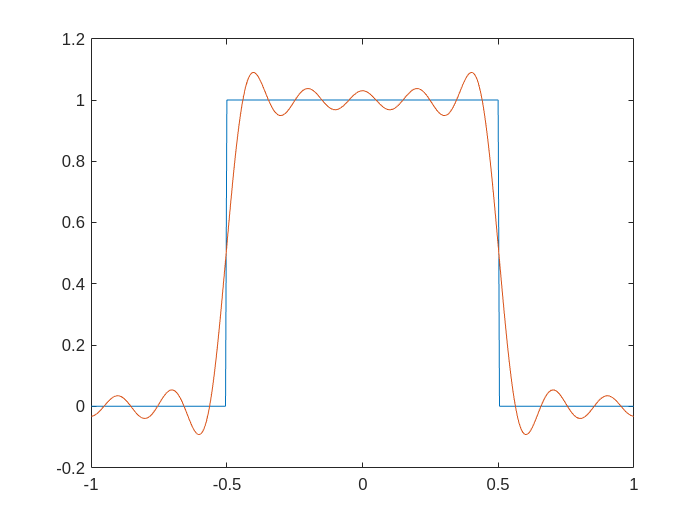

filtro_cuad=t_square.*ventanacuad;
plot(frec,x);
hold on
plot(frec,real(ttof(filtro_cuad)))
hold off

### Ventana de hamming

Usaremos la ventan cuadrada y hacemos un ventana de hamming del mismo tamaño esto se usara para comparar despues. 

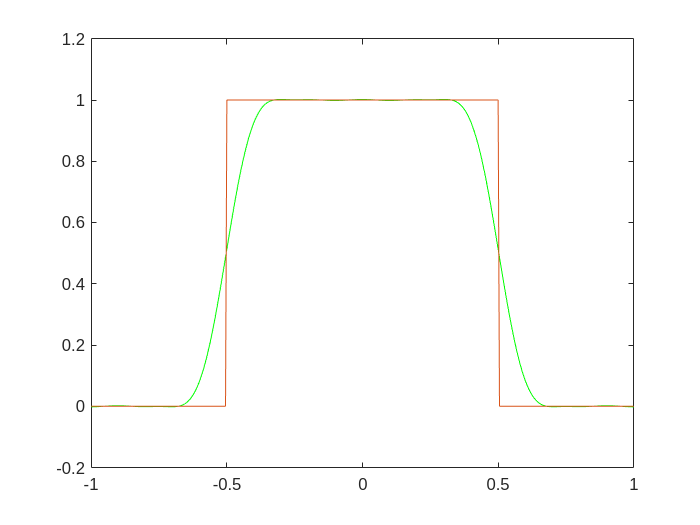

x = int32(x);
y=real(ftot(x));
ventanahamm=zeros(1,lenf);
ventanahamm(191:211)=hamming(21); %Ventana Hamming con valor hasta 21
filtro=y.*ventanahamm;
plot(frec,real(ttof(filtro)), 'g');
hold on
plot(frec,x);
hold off